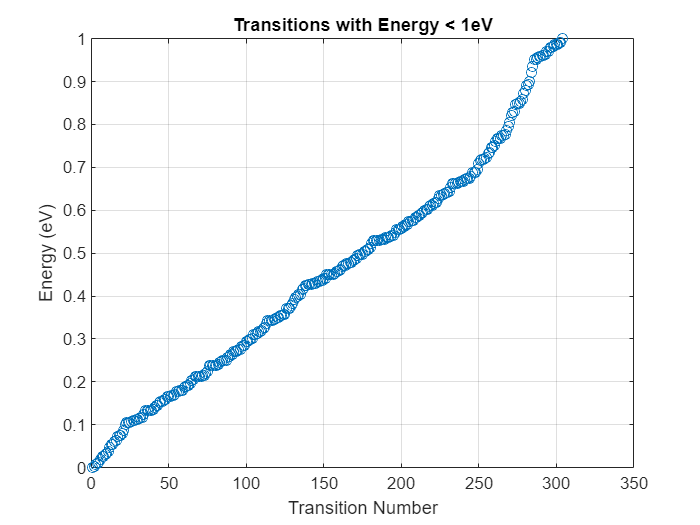

% Load the table from the CSV file
filename = 'quantum_energy_transitions_0-0-0.csv';
quantum_table = readtable(filename);

% Sort the table by the energy transition column
sorted_table = sortrows(quantum_table, 'Energy_Transition_eV');

% Filter to find transitions less than 1 eV
transitions_less_than_1eV = sorted_table(sorted_table.Energy_Transition_eV < 1, :);

% Count the number of transitions less than 1 eV
num_transitions_less_than_1eV = height(transitions_less_than_1eV);

% Plotting
figure;
plot(1:num_transitions_less_than_1eV, transitions_less_than_1eV.Energy_Transition_eV, 'o');
xlabel('Transition Number');
ylabel('Energy (eV)');
title('Transitions with Energy < 1eV');
grid on;


% Display the number of transitions less than 1 eV
disp(['Number of transitions less than 1 eV: ', num2str(num_transitions_less_than_1eV)]);

Number of transitions less than 1 eV: 304
